%b) [a) мы сделали на уроке, начнем с b]
a = 0; b = 2*pi/3;
x = linspace(a,b);
f1 = @(x) (cos(x)+2*sin(x)).^(-2);
y = f1(x);
plot(x,y);
hold on

xr = ginput(2);
plot([xr(1,1) xr(2,1)],[xr(1,2) xr(2,2)],'og');
[x_m,y_m] = fminbnd(f1,xr(1,1),xr(2,1));
plot(x_m,y_m,'or');

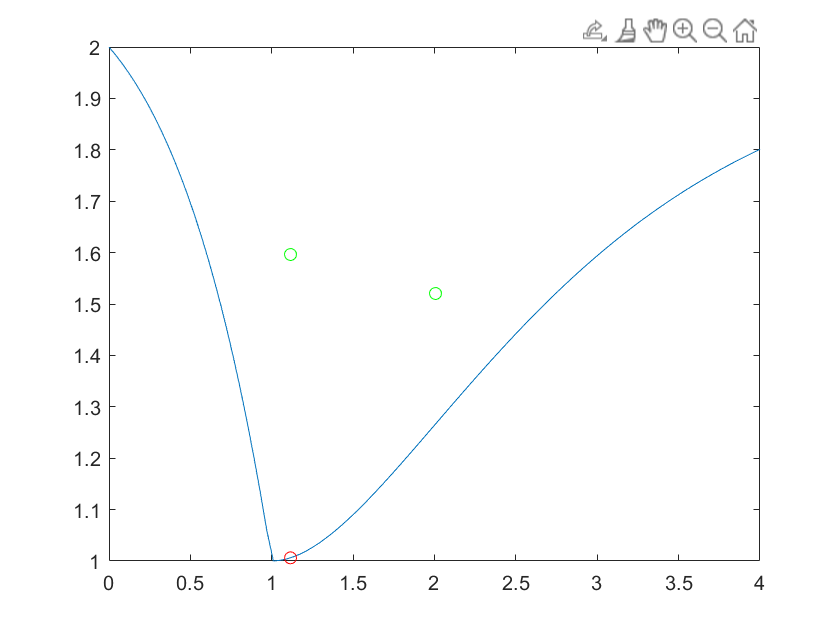

%c)
a = 0; b = 4;
x = linspace(a,b);
f2 = @(x) 2-abs(x).*exp(-abs(x-1));
y = f2(x);
plot(x,y);
hold on

xr = ginput(2);
plot([xr(1,1) xr(2,1)],[xr(1,2) xr(2,2)],'og');
[x_m,y_m] = fminbnd(f2,xr(1,1),xr(2,1));
plot(x_m,y_m,'or');

%d)
a = 0; b = 2*pi;
x = linspace(a,b);
m = 3;
f3 = @(x) func3(x,m); %we need this workaround to make fminbnd work
y = f3(x)

output =     1.0000    0.8734    0.7489    0.6283    0.5138    0.4071    0.3099    0.2239    0.1503    0.0904    0.0451    0.0152    0.0011    0.0031    0.0212    0.0550    0.1040    0.1674    0.2443    0.3332    0.4329    0.5418    0.6580    0.7797    0.9049    1.0317    1.1580    1.2817    1.4009    1.5137    1.6182    1.7127    1.7958    1.8660    1.9224    1.9638    1.9898    1.9999    1.9938    1.9718    1.9341    1.8815    1.8146    1.7346    1.6428    1.5406    1.4298    1.3120    1.1893    1.0634


output =     2.0000    1.6223    1.2627    0.9383    0.6641    0.4522    0.3111    0.2451    0.2543    0.3346    0.4780    0.6732    0.9061    1.1611    1.4221    1.6732    1.8998    2.0898    2.2341    2.3271    2.3671    2.3563    2.3008    2.2095    2.0942    1.9683    1.8460    1.7411    1.6663    1.6322    1.6463    1.7128    1.8319    2.0000    2.2097    2.4502    2.7081    2.9681    3.2141    3.4300    3.6009    3.7140    3.7596    3.7314    3.6276    3.4503    3.2059    2.9049    2.5609    2.1900


output =     3.0000    2.2506    1.5726    1.0286    0.6652    0.5072    0.5553    0.7868    1.1592    1.6164    2.0962    2.5392    2.8959    3.1330    3.2367    3.2138    3.0890    2.9005    2.6934    2.5125    2.3953    2.3665    2.4347    2.5913    2.8125    3.0634    3.3042    3.4968    3.6113    3.6311    3.5560    3.4029    3.2036    3.0000    2.8380    2.7601    2.7985    2.9693    3.2691    3.6743    4.1427    4.6190    5.0413    5.3496    5.4936    5.4401    5.1778    4.7195    4.1016    3.3793


y =     3.0000    2.2506    1.5726    1.0286    0.6652    0.5072    0.5553    0.7868    1.1592    1.6164    2.0962    2.5392    2.8959    3.1330    3.2367    3.2138    3.0890    2.9005    2.6934    2.5125    2.3953    2.3665    2.4347    2.5913    2.8125    3.0634    3.3042    3.4968    3.6113    3.6311    3.5560    3.4029    3.2036    3.0000    2.8380    2.7601    2.7985    2.9693    3.2691    3.6743    4.1427    4.6190    5.0413    5.3496    5.4936    5.4401    5.1778    4.7195    4.1016    3.3793


plot(x,y);
hold on

xr = ginput(2);
plot([xr(1,1) xr(2,1)],[xr(1,2) xr(2,2)],'og');
[x_m,y_m] = fminbnd(f3,xr(1,1),xr(2,1));

output = 0.5014

output = 2.3658

output = 2.3658

output = 0.7400

output = 2.2421

output = 2.5324

output = 0.3697

output = 2.3483

output = 2.4591

output = 0.5185

output = 2.3625

output = 2.3645

output = 0.5197

output = 2.3622

output = 2.3645

output = 0.5193

output = 2.3623

output = 2.3645

output = 0.5192

output = 2.3624

output = 2.3645

output = 0.5193

output = 2.3623

output = 2.3645

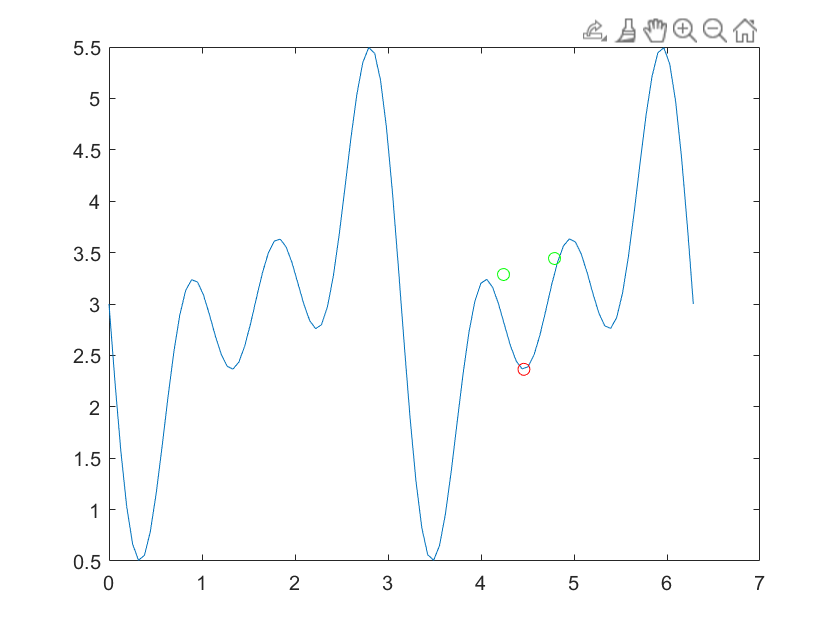

plot(x_m,y_m,'or');

%e)
a  = 0; b = 2*pi; %d = [3,5,2,-1];
x = linspace(a,b);
f4 = @(x) func4(x);
y = f4(x)

y =    39.0000   37.2178   35.6683   34.3079   33.0680   31.8745   30.6680   29.4197   28.1410   26.8827   25.7256   24.7651   24.0921   23.7757   23.8515   24.3173   25.1371   26.2510   27.5897   29.0876   30.6925   32.3698   34.0995   35.8683   37.6594   39.4429   41.1707   42.7770   44.1859   45.3230   46.1296   46.5758   46.6672   46.4462   45.9842   45.3688   44.6872   44.0106   43.3832   42.8181   42.3015   41.8036   41.2934   40.7537   40.1920   39.6440   39.1689   38.8374   38.7143   38.8406


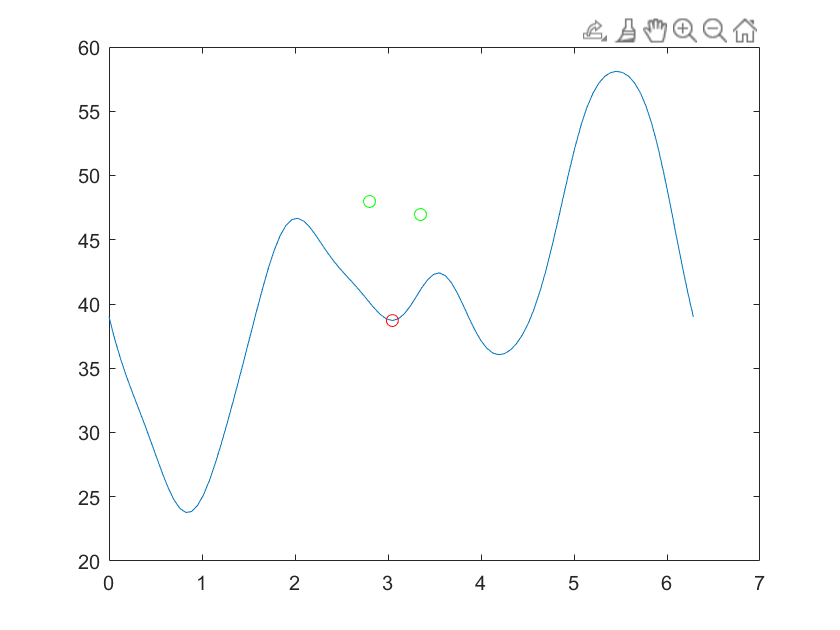

plot(x,y);
hold on

xr = ginput(2);
plot([xr(1,1) xr(2,1)],[xr(1,2) xr(2,2)],'og');
[x_m,y_m] = fminbnd(f4,xr(1,1),xr(2,1));
plot(x_m,y_m,'or');

These functions are for parts d and e

function output = func3(x,m)
    output = 0;
    for i = 1:m
        output = output + (cos(i*x)-sin(i*x)).^2
    end
end

function output = func4(x)
    output = 0;
    d = [3 5 2 -1];
    for i = 1:length(d)
        output = output+(d(1,i)-sin(i.*x)).^2;
    end
end